# Manivela

clear

%EjeManivela=readtable("MatLab cinetica\Reacciones manivela\A3-Eje-manivela-Der.txt","Delimiter"," ");
%EjeManivela=readtable("MatLab cinetica\Reacciones manivela\B3-Eje-manivela-Der.txt","Delimiter"," ");
EjeManivela=readtable("MatLab cinetica\Reacciones manivela\C3-Eje-manivela-Der.txt","Delimiter"," ");


EjeManivela.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"]

EjeManivela = 160×9 table
       T         Fz        Fy         Fx         F           Mz          My       Mx          M     
    _______    ______    _______    _______    ______    __________    ______    _____    __________

          0    22.236    -1340.6    -4345.9      4548    8.6917e+05    -63013    23885    8.7177e+05
    0.01532    23.425    -1412.2    -4578.1      4791    9.1561e+05    -66380    25161    9.1836e+05
    0.03064     24.61    -1483.4    -4809.6    5033.3    9.6191e+05    -69737    26431     9.648e+05
    0.04596    25.788    -1553.7    -5039.8    5273.9    1.0079e+06    -73074    27686     1.011e+06
    0.06128    26.956    -1622.6    -5267.7      5512    1.05


%BielaManivela=readtable("MatLab cinetica\Reacciones manivela\A3-Biela-manivela-Der.txt","Delimiter"," ");
%BielaManivela=readtable("MatLab cinetica\Reacciones manivela\B3-Biela-manivela-Der.txt","Delimiter"," ");
BielaManivela=readtable("MatLab cinetica\Reacciones manivela\C3-Biela-manivela-Der.txt","Delimiter"," ");


BielaManivela.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"]

BielaManivela = 160×9 table
       T         Fz         Fy        Fx        F          Mz         My          Mx          M   
    _______    _______    ______    ______    ______    ________    _______    ________    _______

          0    -4345.7    22.236    1340.6    4547.9    -0.00179    0.01768    -0.00777    0.01939
    0.01532      -4578    23.425    1412.2    4790.9           0          0           0          0
    0.03064    -4809.5     24.61    1483.4    5033.1           0          0           0          0
    0.04596    -5039.6    25.788    1553.7    5273.7           0          0           0          0
    0.06128    -5267.6    26.956    1622.6    5511.9           0       



D_manivela=0.08

D_manivela = 0.0800

d_eje=0.06

d_eje = 0.0600

b_manivela=0.035

b_manivela = 0.0350

h_manivela=D_manivela

h_manivela = 0.0800

W=0.018;
H=0.011;
L=b_manivela;

%4140 T=205
Sut=630  

Sut = 630

Sy=530

Sy = 530

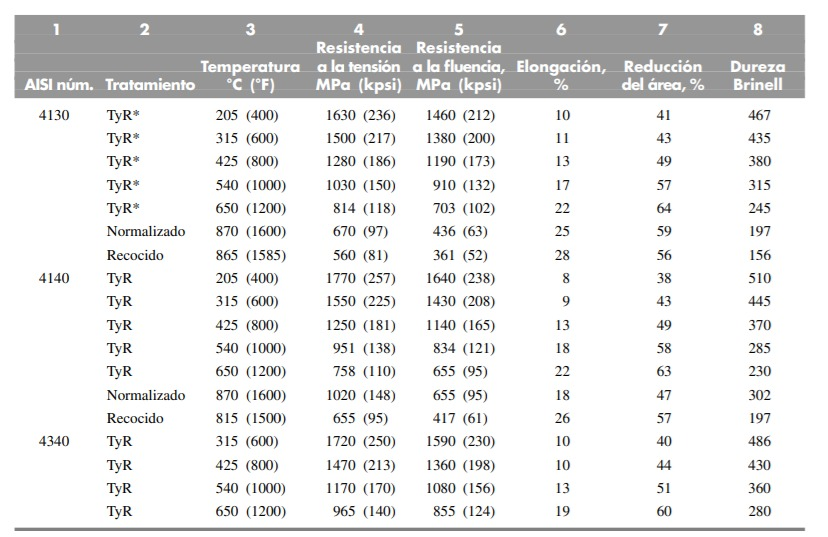

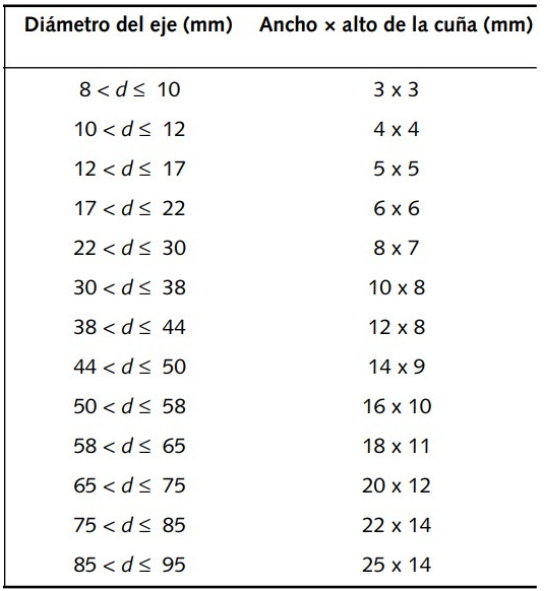



vectorTiempo=BielaManivela.T;
ExtremoEjeFy=-EjeManivela.Fx;
ExtremoEjeFz=EjeManivela.Fz;
ExtremoEjeFx=EjeManivela.Fy;
EjeTorqueMz=EjeManivela.Mz/1000;
EjeTorqueMx=EjeManivela.My/1000;
EjeTorqueMy=-EjeManivela.Mx/1000;
ExtremoBielaFy=BielaManivela.Fz;
ExtremoBielaFz=-BielaManivela.Fy;
ExtremoBielaFx=BielaManivela.Fx;



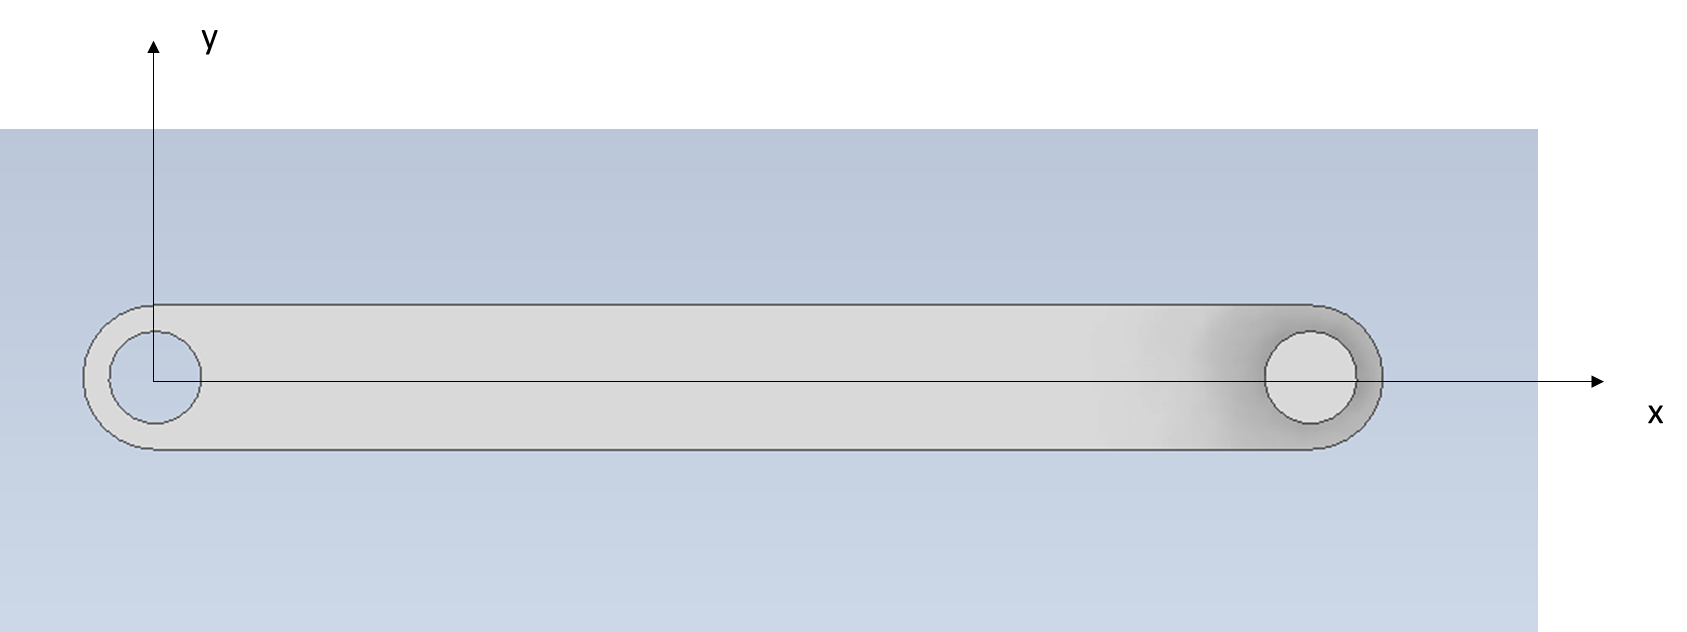

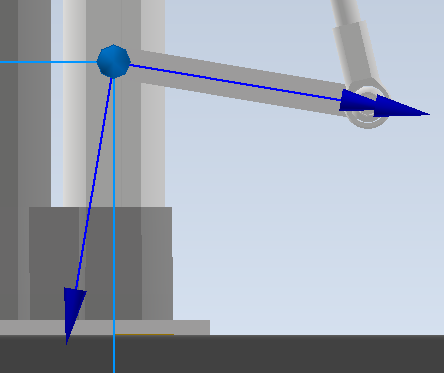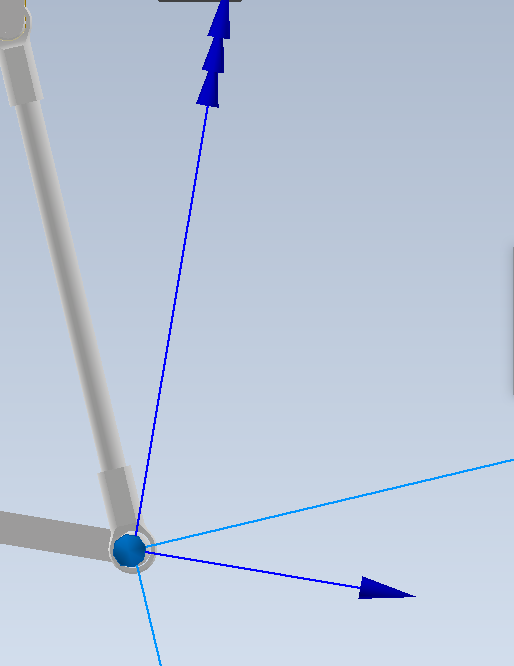

difFx=ExtremoBielaFx+ExtremoEjeFx;
difFy=ExtremoBielaFy+ExtremoEjeFy;
difFz=ExtremoEjeFz+ExtremoBielaFz;


## Análisis unión biela-manivela

ExtremoBielaFy

ExtremoBielaFz

ExtremoBielaFx

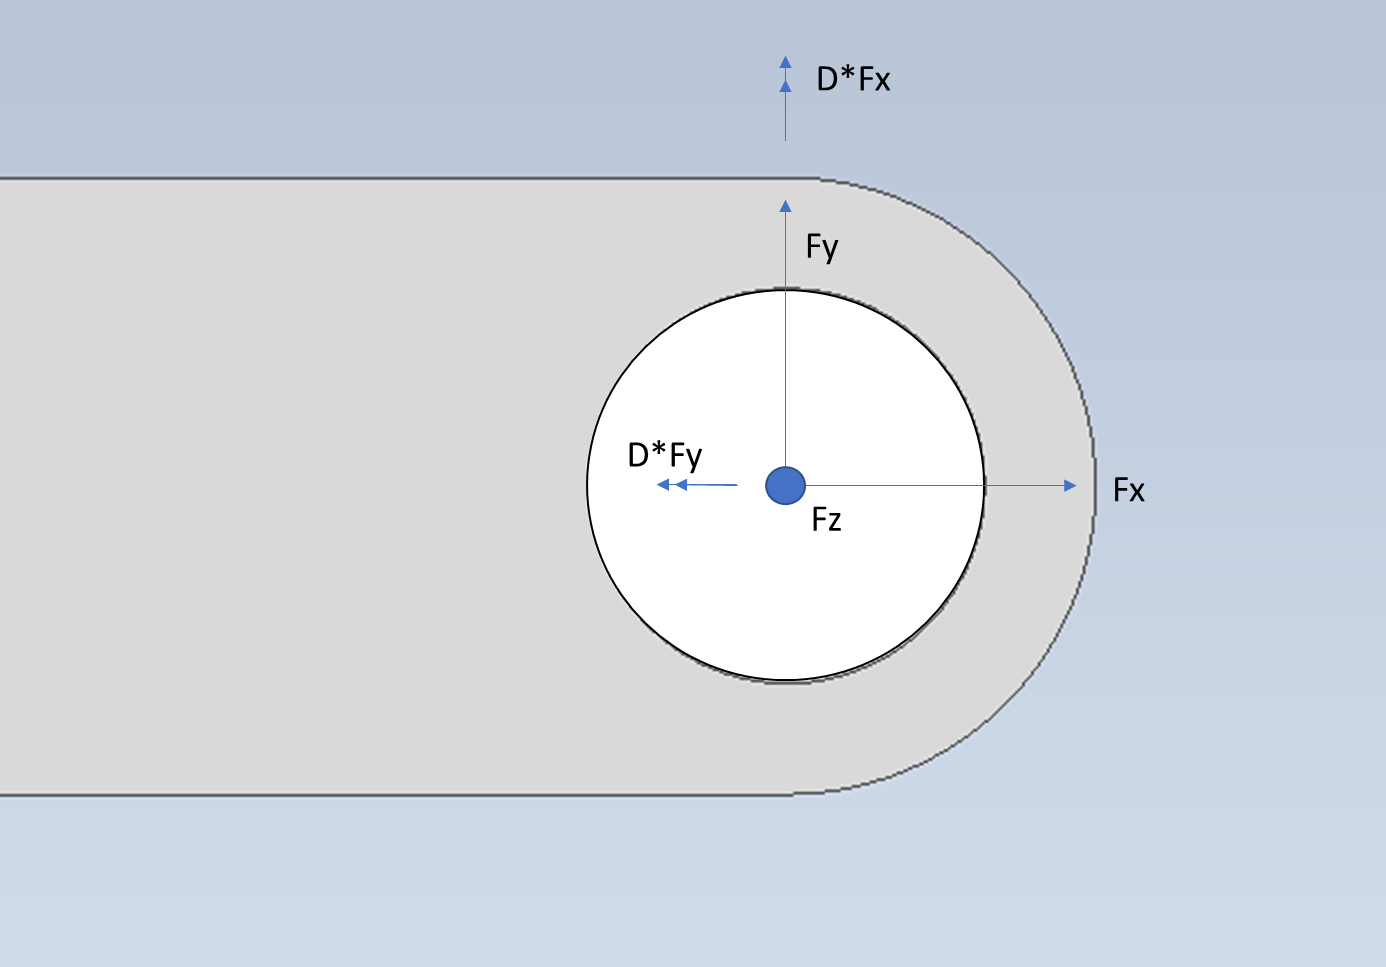

h_bm=0.0125;
D_bm=0.75*0.0254;

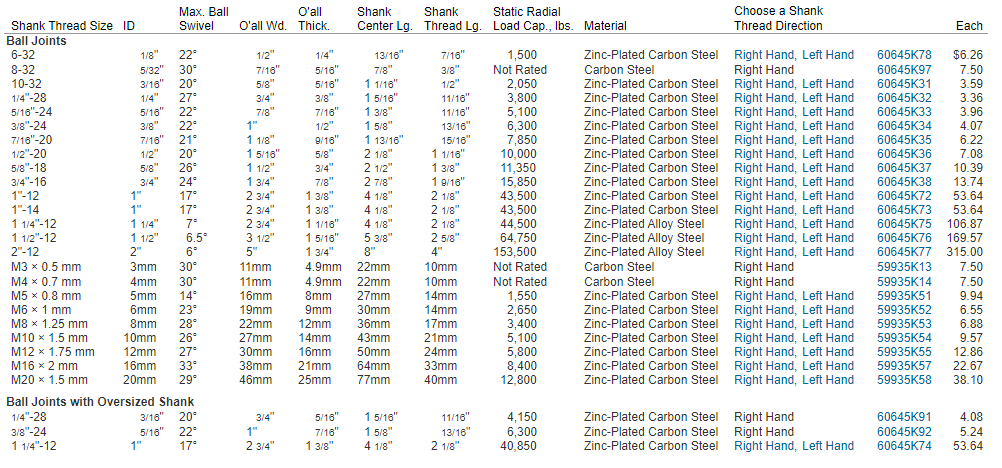

https://www.mcmaster.com/ball-joints/internally-threaded-ball-joint-rod-ends/

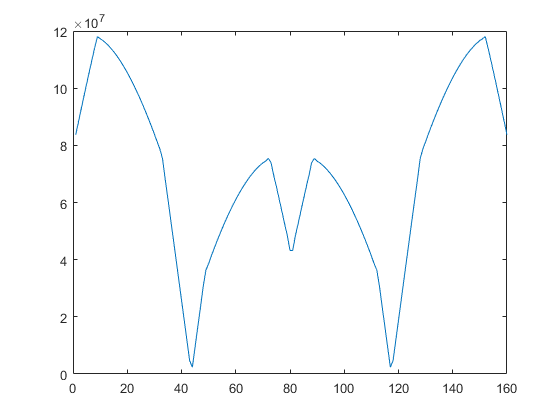

I=pi*D_bm^4/64;
A=pi*D_bm^2/4;
My=h_bm*ExtremoBielaFx;
Mx=h_bm*ExtremoBielaFy;
MT=sqrt(My.^2+Mx.^2);

Sigma_t=MT*0.5*D_bm/I;
Sigma_c=-MT*0.5*D_bm/I;
Sigma_normal=ExtremoBielaFz/A;

Sigma_t_Total=(Sigma_normal+Sigma_t);
Sigma_c_Total=(Sigma_normal+Sigma_c);

plot(Sigma_t_Total)

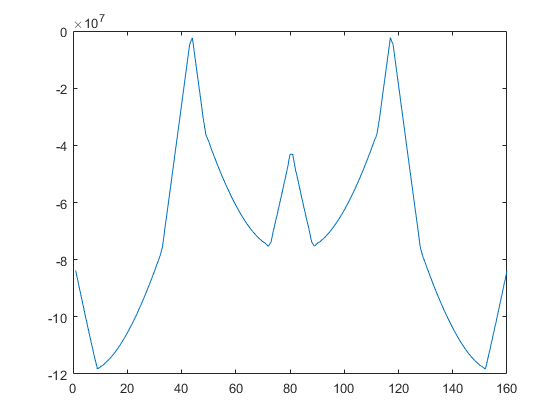


plot(Sigma_c_Total)

### Fatiga

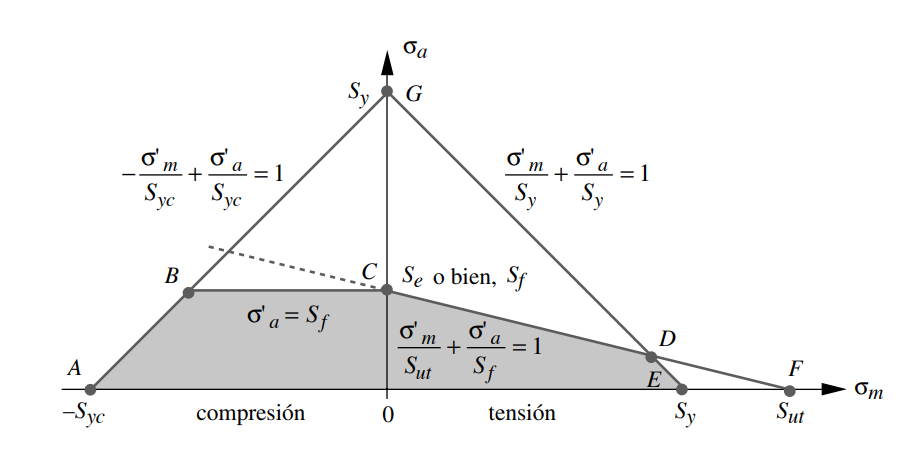

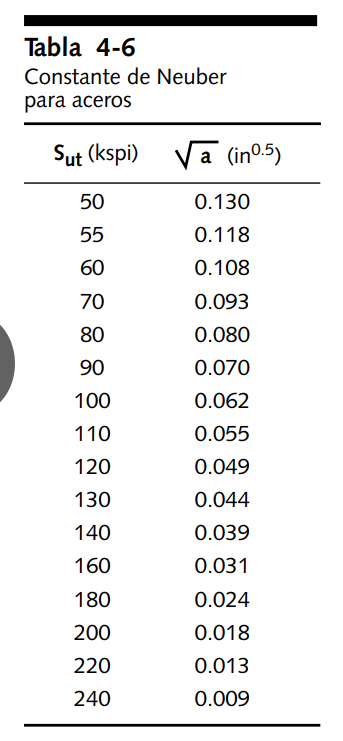

kt=2

kt = 2

neuberF=0.07 %Corregir neuber

neuberF = 0.0700

neuberT=0.055

neuberT = 0.0550

radioMuesca=0.1 %inches

radioMuesca = 0.1000

qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));

KfSold=1+qFlexion*(kt-1)

KfSold = 1.8188

KfsmSold=1+qTorsion*(kt-1)

KfsmSold = 1.8518


mega=1000000;

sigmaAc=KfSold*0.5.*abs(max(Sigma_c_Total)-min(Sigma_c_Total))/mega   %esfuerzo alternante

sigmaAc = 105.3867

sigmaMc=KfSold*0.5.*abs(max(Sigma_c_Total)+min(Sigma_c_Total))/mega   %esfuerzo medio

sigmaMc = 109.6677


sigmaAt=KfSold*0.5.*abs(max(Sigma_t_Total)-min(Sigma_t_Total))/mega   %esfuerzo alternante

sigmaAt = 105.1823

sigmaMt=KfSold*0.5.*abs(max(Sigma_t_Total)+min(Sigma_t_Total))/mega

sigmaMt = 109.4712

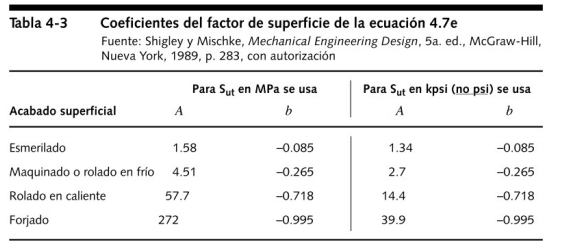

#### Factores de corrección


Fsup=4.51*(Sut)^(-0.265)

Fsup = 0.8172

Fcar=1; %flexion =1
Ftem=1;

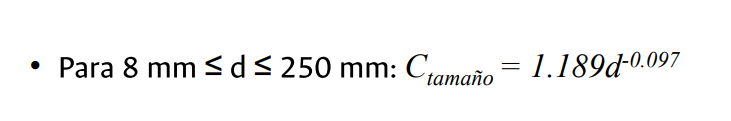

Ctam=1.189*(D_bm*1000)^(-0.097)

Ctam = 0.8934

Ccon=0.814 % 99%

Ccon = 0.8140

if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end

Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 187.2054

#### Diagrama de Goodman modificado

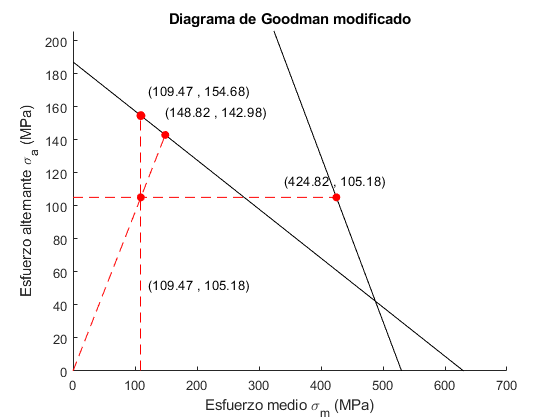

FS1 = 1.4706

FS2 = 1.3594

FS3 = 3.8806

FS_union_biela_t = 1.3594

FS_union_biela_t=diagramaGoodman(sigmaAt,sigmaMt,Sut,Sy,Se,true)

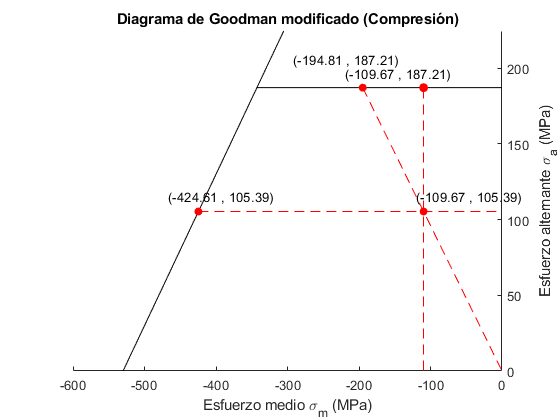

FS1 = 1.7764

FS2 = 1.7764

FS3 = 3.8718

FS_union_biela_c = 1.7764


FS_union_biela_c=diagramaGoodman(sigmaAc,sigmaMc,Sut,Sy,Se,false)

## Análisis unión eje-manivela


A_seccion=0.5*b_manivela*(D_manivela-d_eje)-b_manivela*0.004

A_seccion = 2.1000e-04

J=pi/32*(D_manivela^2-d_eje^2)

J = 2.7489e-04

I=pi/64*(D_manivela^2-d_eje^2)

I = 1.3744e-04

r_externo=0.5*D_manivela

r_externo = 0.0400


Kt=1.8

Kt = 1.8000


%NPI kts

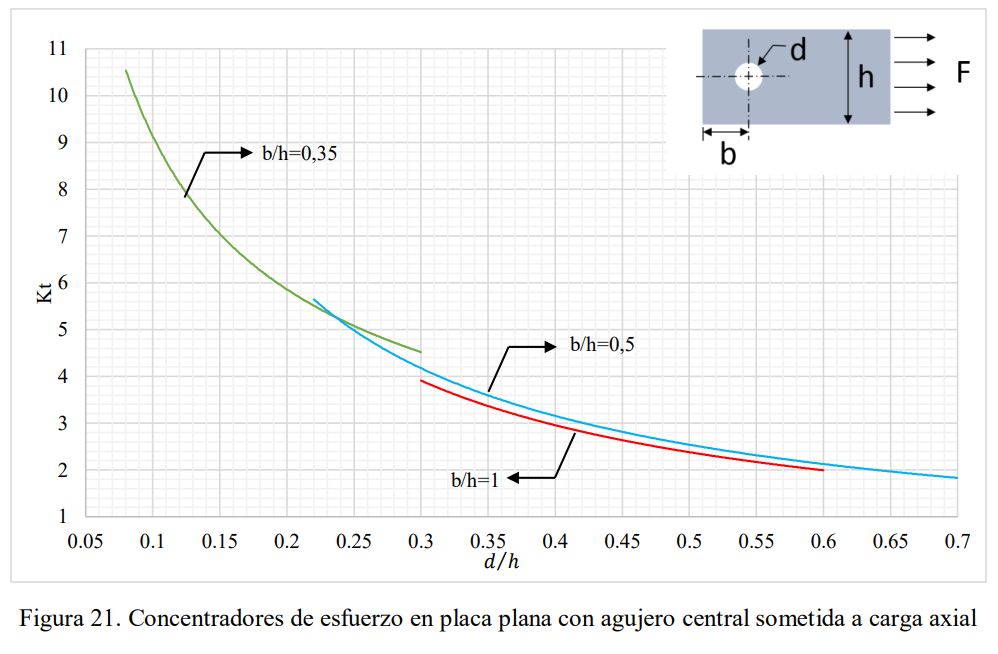

radioMuesca=0.1 %inches

radioMuesca = 0.1000

qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));
Kf=1+qFlexion*(kt-1)

Kf = 1.8188

Kfsm=1+qTorsion*(kt-1)

Kfsm = 1.8518





Sigma_Fx=ExtremoEjeFx/A_seccion;  %Carga axial:Siempre -i
Sigma_Mz=-EjeTorqueMz*r_externo/I; %Momento flector: +y->-i,-y->i
sigma_My=EjeTorqueMy*r_externo/I; %Momento flector: +z->i,-z->-i


tau_Vy=ExtremoEjeFy/A_seccion; %Carga cortante en j
tau_Vz=ExtremoEjeFz/A_seccion; %Carga cortante en k
tau_Mx=EjeTorqueMx*r_externo/J; %Momento cortante:  +y->+k,-y->-k


Sigma_total=Sigma_Fx+Sigma_Mz+sigma_My;
tau_total=sqrt(tau_Vy.^2+(tau_Vz+tau_Mx).^2);


Sigma_Alternante=0.5*(max(Sigma_total)-min(Sigma_total))

Sigma_Alternante = 4.9340e+06

Sigma_Medio=0.5*(max(Sigma_total)+min(Sigma_total))

Sigma_Medio = -4.3416e+06

Tau_Alternante=0.5*(max(tau_total)-min(tau_total))

Tau_Alternante = 1.4306e+07

Tau_Medio=0.5*(max(tau_total)+min(tau_total))

Tau_Medio = 1.4911e+07


sigmaA=sqrt((Kf*Sigma_Alternante).^2+3*(Kfsm*Tau_Alternante).^2)/mega

sigmaA = 46.7545

sigmaM=sqrt((Kf*Sigma_Medio).^2+3*(Kfsm*Tau_Medio).^2)/mega

sigmaM = 48.4758

#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=0.7; %flexion =1
Ftem=1;

A_95=0.05*A_seccion*0.5;
d_eq=sqrt(A_95/0.0766);

Ctam=1.189*(d_eq*1000)^(-0.097)

Ctam = 0.9686


Ccon=0.897;

if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 156.5639

#### Diagrama de Goodman

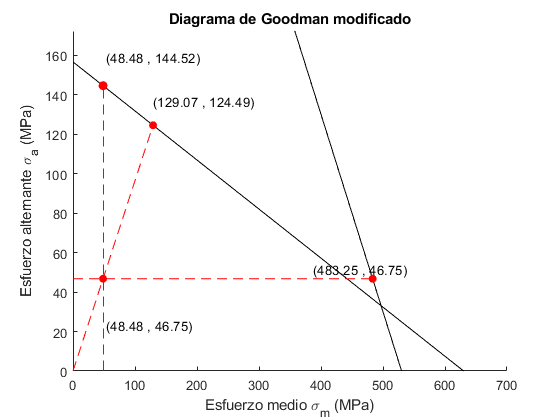

FS1 = 3.0910

FS2 = 2.6626

FS3 = 9.9688

FS_cortante_eje = 2.6626

FS_cortante_eje=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,true)

## Análisis cuña-cuñero Cortante

Sut=630  

Sut = 630

Sy=530

Sy = 530


%parametros cuña


A_t=W*L;

r_eje=0.5*d_eje;
Torque=EjeTorqueMz;
r_cuna=0.03*d_eje;


Carga_cortante=Torque/r_eje;
tau_V=Carga_cortante/A_t;

sigmaA=sqrt(3)*0.5*(max(tau_V)-min(tau_V))/mega

sigmaA = 93.7031

sigmaM=sqrt(3)*0.5*(max(tau_V)+min(tau_V))/mega

sigmaM = 18.7509

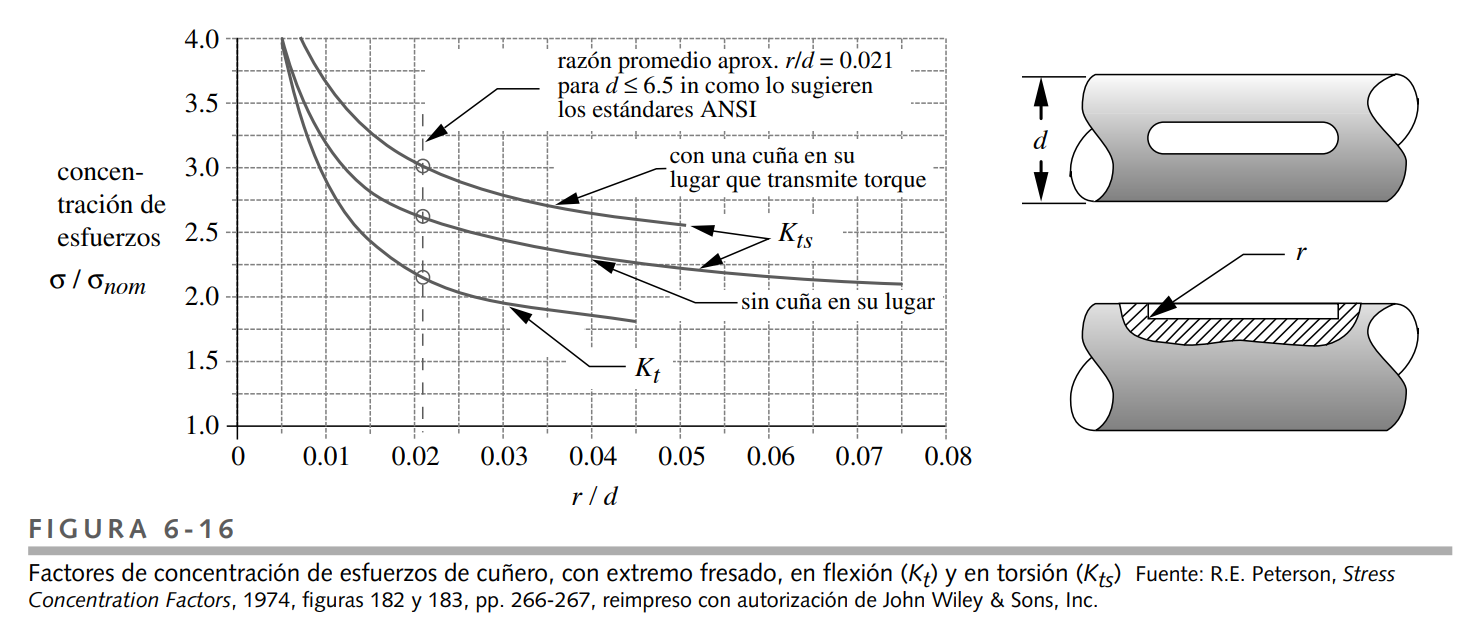

#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=1; %flexion =1
Ftem=1;
Ccon=0.897;


A_95=0.05*L*W

A_95 = 3.1500e-05

d_eq=sqrt(A_95/0.0766)

d_eq = 0.0203

Ctam=1.189*(d_eq*1000)^(-0.097)

Ctam = 0.8880


if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 205.0469

#### Diagrama de Goodman

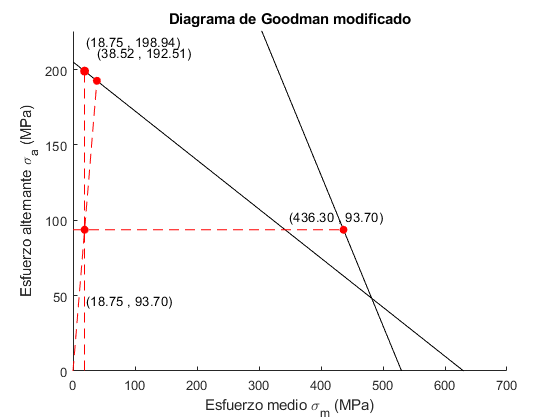

FS1 = 2.1231

FS2 = 2.0545

FS3 = 23.2680

FS_cortante_cuna = 2.0545

FS_cortante_cuna=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,true)

## Análisis cuña-cuñero aplastamiento


Sec_ap=5.382*0.001

Sec_ap = 0.0054


A_sigma=Sec_ap*L;

sigma_V=Carga_cortante/A_sigma;

sigmaA=0.5*(max(sigma_V)-min(sigma_V))/mega

sigmaA = 180.9347

sigmaM=0.5*(max(sigma_V)+min(sigma_V))/mega

sigmaM = 36.2069

#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=0.7; %flexion =1
Ftem=1;
Ccon=0.897;

A_95=0.05* H*W

A_95 = 9.9000e-06

d_eq=sqrt(A_95/0.0766)

d_eq = 0.0114

Ctam=1.189*(d_eq*1000)^(-0.097)

Ctam = 0.9392


SeSC=0.5*Sut;
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 151.8207

#### Diagrama de Goodman

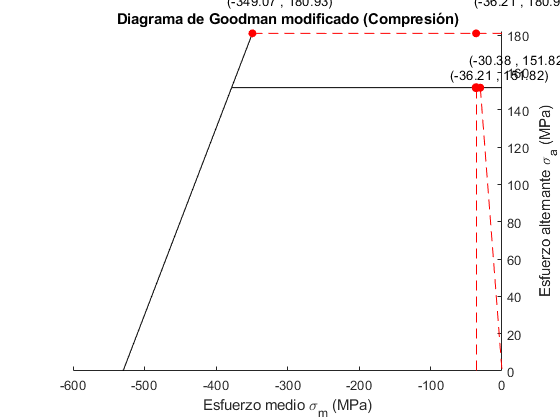

FS1 = 0.8391

FS2 = 0.8391

FS3 = 9.6409

FS_aplastamiento_cuna = 0.8391

FS_aplastamiento_cuna=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,false)

function FSMin=diagramaGoodman(EsigmaA,EsigmaM,ESut,ESy,ESe,tension)
syms x1 x2 x3 x4

if(tension)
sigmaA=EsigmaA;
sigmaM=EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;


FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));

figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(FSm,1.1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(0.8*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado")
FS1=goodManM(sigmaM)/sigmaA
FS2=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]);

else
    
%Fc2=Se==Sy+x3;
%Fr2=sigmaA.*x4/sigmaM==Se;

%lineaFN=@(x) Sy+x;
%FSn=double(solve(Fc2,x3));
%FSp=double(solve(Fr2,x4));
%fplot(lineaFN,[-Sy 0],"k")
%fplot(Se,[FSn 0],"k")
    
sigmaA=EsigmaA;
sigmaM=-EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy+x;
goodManM=@(x)  Se;
lineaC=@(x)     sigmaA.*x./sigmaM;
Fr=sigmaA.*x1/sigmaM==Se;
Fq= Sy+x2==sigmaA;
Fc2=Se==Sy+x3;
FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSn=double(solve(Fc2,x3));
figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[-Sy 0],"k")
fplot(goodManM,[FSn 0],"k")
fplot(lineaC,[FSm 0],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[FSy 0],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,1.1*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(2*sigmaM,1.05*Se,sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(1.5*FSm,1.1*Se,sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(1.1*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.2])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado (Compresión)")
ax=gca;
ax.YAxisLocation = 'right';
FS1=Se/sigmaA
FS2=sqrt(FSm^2+Se^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]); 
end
end